## Figure 2a

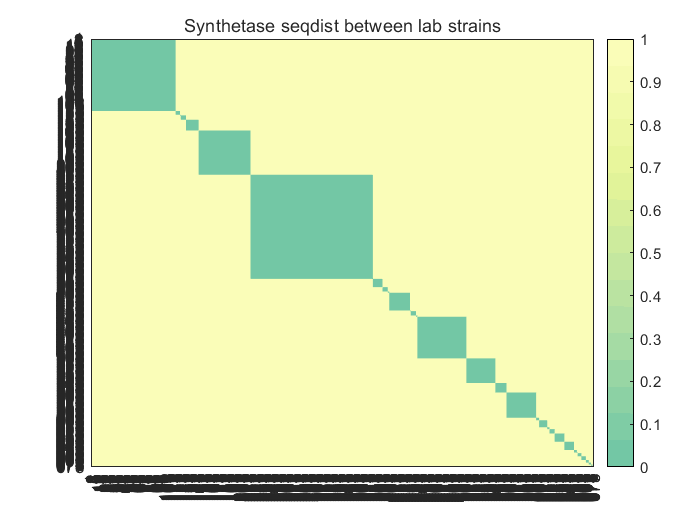

%Co-evolution Pairing Algorithm code in the ./Figure2a_Algorithm/
clc;
clear;
addpath './Figure2a_Algorithm/';  
load ./data/data/rec_seq.mat;
load ./data/data/pdist_syn.mat;

disttrehs=0.3;
if ~exist('./output/distm_syn_1.mat','file')
    seqdist_pepA569_zd=pdist_569_syn_zd(1:678,1:678);
    for i =1:678
            for j = 1:678
                seqdist_pepA569_zd(j, i) = seqdist_pepA569_zd(i, j);
            end
    end
    
    disttrehs=0.3;
    distm_syn=seqdist_pepA569_zd;
    distm_syn(distm_syn<=disttrehs)=0;
    distm_syn(distm_syn>disttrehs)=1;
    addpath './algorithm';
    [mat_new, cluster_order] = roughlinkage_zd(distm_syn);
    distm_syn_1=mat_new(cluster_order,cluster_order);
    save ('./output/distm_syn_1.mat',"distm_syn_1",'cluster_order');
else
    load('./output/distm_syn_1.mat');
end

addpath './cbrewer/';   

figure;
h=heatmap(distm_syn_1,'GridVisible','off');
%caxis([0 0.8])
title('Synthetase seqdist between lab strains')
Down_color = cbrewer('div', 'Spectral',115, 'linear');%
Down_color = Down_color([60:2:90],:);
h.Colormap = flip(Down_color);
h.CellLabelColor = 'none';
h.FontName = 'Arial';
colorbar 

## A randomly selected fpva

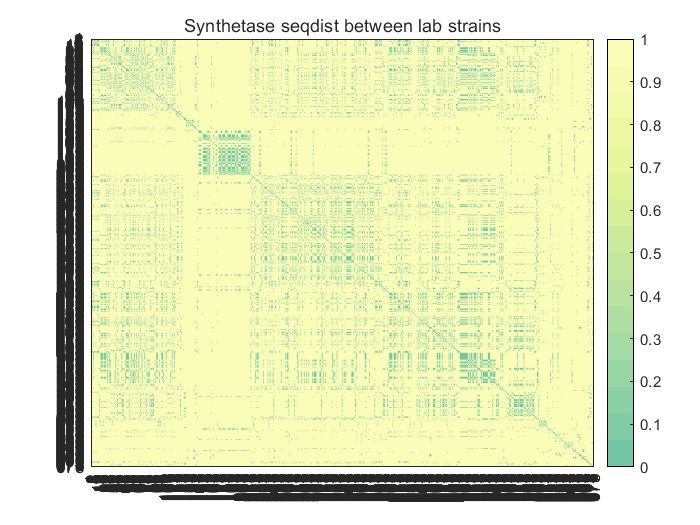


if ~exist('./output/distm_rec_first.mat','file')
    recseq_569=seq_569_1vMore.rec_seq(1:678);
    recseq_569_clusterorder=recseq_569(cluster_order);
    recseq_569_clusterorder_first1=[];
    num=0;
    for i=1:678
           recseq_569_clusterorder_first1.seq(i,1)=recseq_569_clusterorder(i).seq(1);
    end
    recseq_569_clusterorderfirst1_2= recseq_569_clusterorder_first1.seq;
    
    
    
    pdist_569_1106_rec_first1=zeros(678,678);
    for i = 1:678
        
            parfor j = 1:678
               
                pdist_569_1106_rec_first1(i, j) = seqpdist({recseq_569_clusterorderfirst1_2{i},recseq_569_clusterorderfirst1_2{j}}, 'method', 'p-distance', 'PairwiseAlignment', true);
                 
            end
    end
    for i = 1:678
        i
            for j = 1:678
                
                 pdist_569_1106_rec_first1(j, i)  = pdist_569_1106_rec_first1(i, j);
            end
    end
    save('./output/distm_rec_first.mat','pdist_569_1106_rec_first1');
else
    load('./output/distm_rec_first.mat');
end

pdist_569_1106_rec_first1(pdist_569_1106_rec_first1<=disttrehs)=0;
pdist_569_1106_rec_first1(pdist_569_1106_rec_first1>disttrehs)=1;

[distm_rec_first,~] = roughlinkage_zd(pdist_569_1106_rec_first1);

figure;
h=heatmap(distm_rec_first,'GridVisible','off');
%caxis([0 1])
title('Synthetase seqdist between lab strains')
Down_color = cbrewer('div', 'Spectral',115, 'linear');%
Down_color = Down_color([60:2:90],:);
h.Colormap = flip(Down_color);
h.CellLabelColor = 'none';
h.FontName = 'Arial';
colorbar 

## The selfreceptor obtained by the algorithm

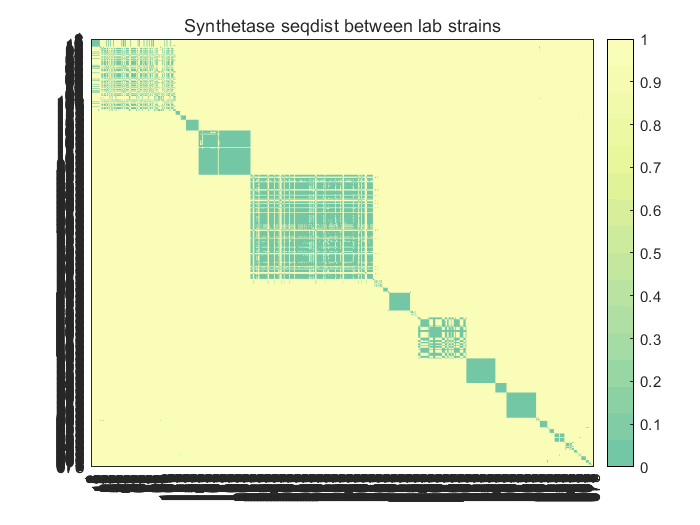

%Run the program 5 times and select the result with the highest preparation rate as the final self-receptor
load ./data/algorithm_result_5.mat;
usenum=find(result(:,600,4)==max(result(:,600,4)),1);
%Get the selfrec and cheaterrec of the partial producer
selfnum=zeros(length(result_num),1);
for i=1:length(result_num)
     selfnum(i,1)=result_num(usenum,i);
end

selfrec_partial=[];
cheaterec_partial=[];
num1=0;
for i= 1:length(seq_569_1vMore.rec_seq)
    for j=1:length(seq_569_1vMore.rec_seq(i).seq)
        if j==selfnum(i,1)
            selfrec_partial.sequence{i,1}=seq_569_1vMore.rec_seq(i).seq{j,1};
            selfrec_partial.num{i,1}=length(seq_569_1vMore.rec_seq(i).seq);
        else
            num1=num1+1;
           cheaterec_partial.sequence{num1,1}=seq_569_1vMore.rec_seq(i).seq{j,1};
            cheaterec_partial.strainname{num1,1}=seq_569_1vMore.strain_name{i,1};
        end
    end
end


if ~exist('./output/distm_rec_algorithm.mat','file')
    selfrec_seq=selfrec_partial.sequence(1:678);
    selfrec_seq_clusterorder=selfrec_seq(cluster_order);
    
    
    distm_rec_algorithm=zeros(678,678);
    for i = 1:678
        i
            parfor j = 1:678
               
                distm_rec_algorithm(i, j) = seqpdist({selfrec_seq_clusterorder{i},selfrec_seq_clusterorder{j}}, 'method', 'p-distance', 'PairwiseAlignment', true);
                
            end
    end
    for i = 1:678
        i
            for j = 1:678
                distm_rec_algorithm(j, i) = distm_rec_algorithm(i, j);
            end
    end
    save('./output/distm_rec_algorithm.mat','distm_rec_algorithm');
else
    load('./output/distm_rec_algorithm.mat');
end
distm_rec_algorithm(distm_rec_algorithm<=disttrehs)=0;
distm_rec_algorithm(distm_rec_algorithm>disttrehs)=1;
[distm_rec_algorithm_1,~] = roughlinkage_zd(distm_rec_algorithm);

figure;
h=heatmap(distm_rec_algorithm,'GridVisible','off');
%caxis([0 0.8])
title('Synthetase seqdist between lab strains')
Down_color = cbrewer('div', 'Spectral',115, 'linear');%
Down_color = Down_color([60:2:90],:);
h.Colormap = flip(Down_color);
h.CellLabelColor = 'none';
h.FontName = 'Arial';
colorbar 


corr2(distm_syn_1,distm_rec_first)

ans = 0.1739

corr2(distm_syn_1,distm_rec_algorithm_1)

ans = 0.8466

## Figure 2b

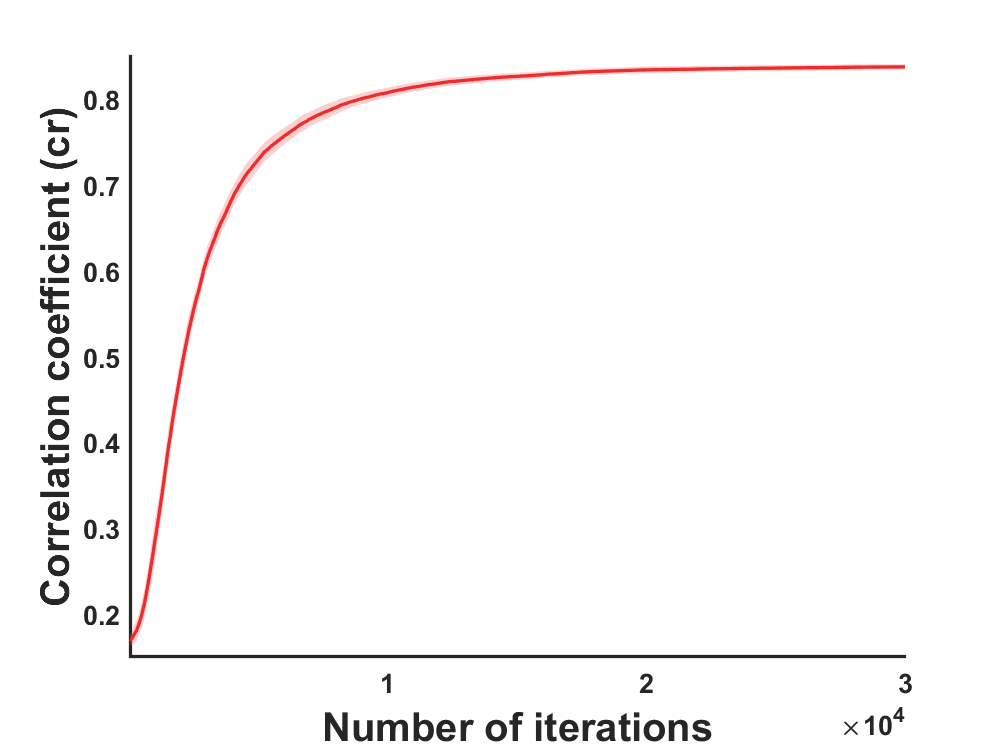


load ./data/algorithm_result_50.mat;
p_mean = mean(result(:,:,2), 1);%2 is cr
p_std = std(result(:,:,2), 1);


h = figure;hold on;


    x = result(1,:,1)';
    y = p_mean';
    z = p_std';
    h1 = fill([x; flipud(x)],[y-z; flipud(y+z)],'r','FaceColor',[238 99 99]/255,'EdgeColor','none');%FaceColor为填充颜色，EdgeColor为边框颜色
    set(h1,'edgealpha',0,'facealpha',0.3);
    
 
f1 = plot(x, y, '-','linewidth', 2, "Color",[238 44 44]/255);

axis([-inf inf 0.15 0.85])

set(gca,'xtick',[0:10000:30000]);

set(gca,'ticklength',[0 0])
set(gca,'Linewidth',2);
set(gca,'FontSize',16,'FontWeight','bold');
xlabel('Number of iterations' ,'FontSize',24,'FontWeight','bold');
ylabel('Correlation coefficient (cr)' ,'FontSize',24,'FontWeight','bold');
set(h, 'position', [100 100 800 600]);

## Figure 2c

data=readtable('./data/compare_data.xlsx');

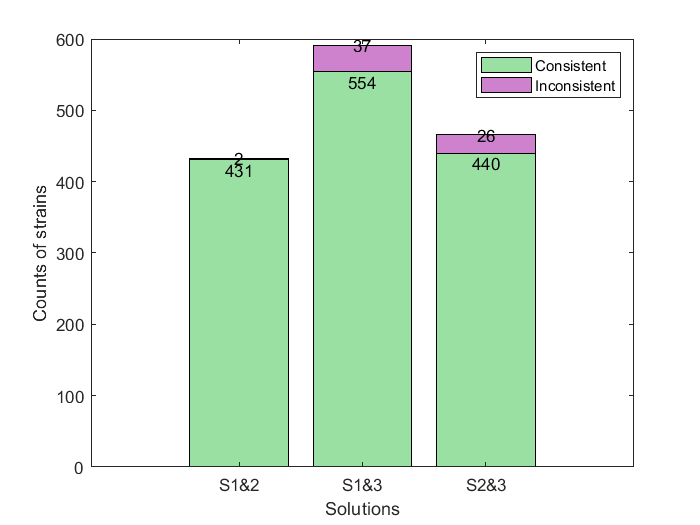

a1=length(find(data.s1_s2==1));
b1=length(find(data.s1_s2==0));

a2=length(find(data.s1_s3==1));
b2=length(find(data.s1_s3==0));

a3=length(find(data.s2_s3==1));
b3=length(find(data.s2_s3==0));

figure;
b=bar([1,2,3],[a1,a2,a3;b1,b2,b3],0.8,'stacked');
b(1).FaceColor = "#99E0A2";
b(2).FaceColor = "#CE82CE";

xlabel('Solutions');
ylabel('Counts of strains');
legend('Consistent', 'Inconsistent');

x = [1, 2, 3];
y1 = [a1, a2, a3]; 
y2 = [b1, b2, b3]; 
for i = 1:numel(x)
    text(x(i), y1(i), num2str(y1(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top');
    text(x(i), y1(i) + y2(i), num2str(y2(i)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
end

xticks([1, 2, 3]);
xticklabels({'S1&2', 'S1&3', 'S2&3'});

## Figure 2d

load ./data/data/recgroup.mat;
load ./data/data/allpep45seqdist.mat;
load ./data/data/rec_seqdist_1.mat;
load ./data/data/rec_seqdist_2.mat;
load ./data/data/rec_infor.mat;
rec1989.seqdist678910=[rec_seqdist_1;rec_seqdist_2];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
groupsize=zeros(1,totalgnum);
group_typebelong=zeros(4,totalgnum);
node_groupid=recgroup;
changedleaforder_bygroups=leaforder_alonesp;
for g=1:totalgnum
    members_rec=find(node_groupid==g);
    members_straintype=rec1989.sptypeid(members_rec);
    group_typebelong(:,g)=[sum(members_straintype==1),sum(members_straintype==2),sum(members_straintype==3),sum(members_straintype==4)];
    thisg_members=find(node_groupid(changedleaforder_bygroups)==g);
    groupsize(g)=length(thisg_members);
end

a=find(group_typebelong(1,:)~=0);
b=find(group_typebelong(2,:)~=0);
c=union(b,a);
sizeex=groupsize(c)

sizeex =    239   174   608    29    16    29    11     9    14    40    48   402   184    77    23    92    84     5    11    18    44     6    24     8    21    45    44    36   138    10    47    46    16    63    25     3    14    11    39    70     2     9   350   627    84    49   423


sum(sizeex)

ans = 4367

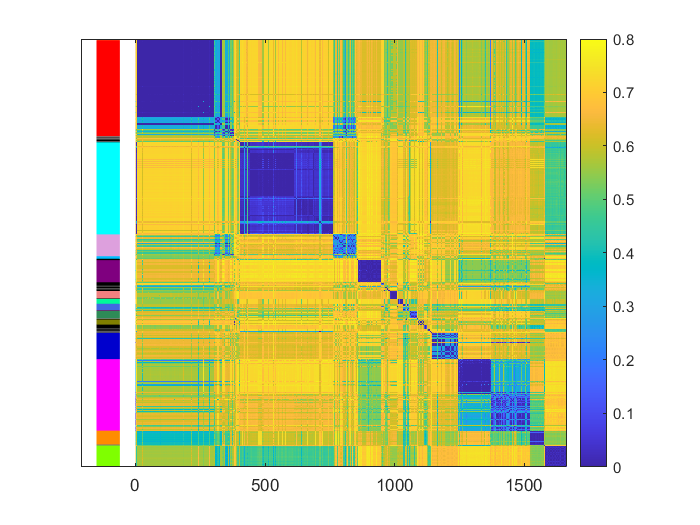

g47=group_typebelong(:,c);

recg=1:94;
group_typebelong_1=group_typebelong(:,c);
recgroup_orderbysize_1=recg(c);
groupsize_1=groupsize(c);

%Receptor
aa=ismember(recgroup,c);
recgroup_use=recgroup(aa);
recseqdist_use=rec1989.seqdist678910(aa,aa);
recsptypeid_use=rec1989.sptypeid(aa);
recseq_use=rec1989.seq(aa);
recstrainname_use=rec1989.strainname(aa);
[recgroup_last,recorder]=sort(recgroup_use);
recsptypeid_last=recsptypeid_use(recorder);
recseqdist_last=recseqdist_use(recorder,recorder);
%Synthetase
syngroup_use=recgroup_use(1:1664);
synseqdist_use=allpep45seqdist_zd;
synsptypeid_use=recsptypeid_use(1:1664);
synstrainname_use=Acomb_1682.spname;
[syngroup_last,synorder]=sort(syngroup_use);
synsptypeid_last=synsptypeid_use(synorder);
synseqdist_last=synseqdist_use(synorder,synorder);

%Synthetase
figure;
imagesc(synseqdist_last);
colorbar
caxis([0 0.8])
hold on;
set(gca,'ytick',[]);


groupsize_thresh=30;
colorgroups_1=readtable('./data/colorcode17.xlsx');
colorgroups_temp=colorgroups_1(:,3:5);
colorgroups=table2array(colorgroups_temp);

recgsize=tabulate(syngroup_last);
uniquerecg=find(recgsize(:,2)>0);
for i=1:length(uniquerecg)
        g=uniquerecg(i);
        b=find(colorgroups_1.Rec_groupid==g);
        thisg_members=find(syngroup_last==g);
        if ~isempty(b)
            colorcode=colorgroups(b,:);
        elseif mod(i,2)==1
            colorcode=[0 0 0];
        else
            colorcode=[123/255,123/255,123/255];
        end
    
        %text(-55, mean(thisg_members),num2str(g));
        ph=patch([-150,-60,-60,-150],[thisg_members(1)-1,thisg_members(1)-1,thisg_members(end),thisg_members(end)],colorcode);
        ph.LineStyle='none';                  
end
xlim([-210,size(synseqdist_last,1)+1])

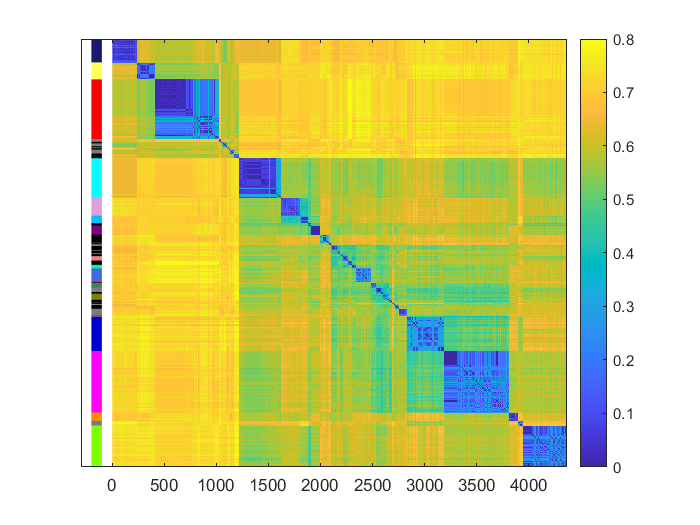


%Receptor
figure;
imagesc(recseqdist_last);
colorbar
caxis([0 0.8])
hold on;
set(gca,'ytick',[]);


groupsize_thresh=30;
colorgroups_1=readtable('./data/colorcode17.xlsx');
colorgroups_temp=colorgroups_1(:,3:5);
colorgroups=table2array(colorgroups_temp);

recgsize=tabulate(recgroup_last);
uniquerecg=find(recgsize(:,2)>0);
for i=1:length(uniquerecg)
        g=uniquerecg(i);
        b=find(colorgroups_1.Rec_groupid==g);
        thisg_members=find(recgroup_last==g);
        if ~isempty(b)
            colorcode=colorgroups(b,:);
        elseif mod(i,2)==1
            colorcode=[0 0 0];
        else
            colorcode=[123/255,123/255,123/255];
        end
        %text(-55, mean(thisg_members),num2str(g));
      
        ph=patch([-200,-100,-100,-200],[thisg_members(1)-1,thisg_members(1)-1,thisg_members(end),thisg_members(end)],colorcode);
        
        ph.LineStyle='none';                  
end
xlim([-300,size(recseqdist_last,1)+1])

## Figure S3

[value,order]=sort(groupsize,'descend');
gnumtoshow=find(groupsize(order)>0, 1, 'last' )

gnumtoshow = 94

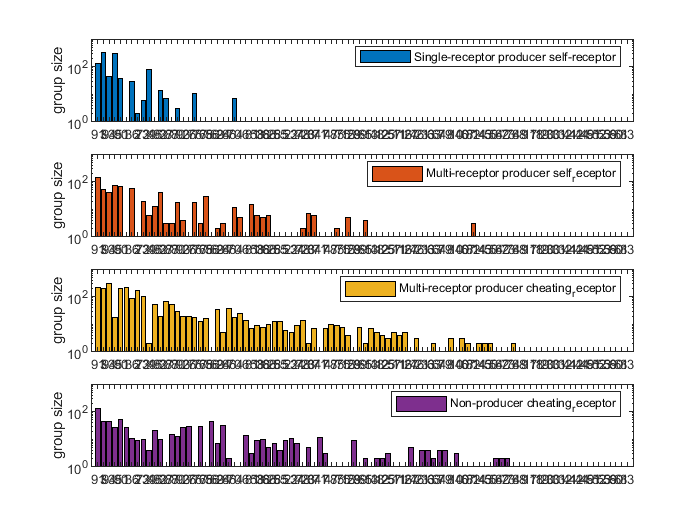


GSH=group_typebelong(:,order(1:gnumtoshow));
a=find(GSH(1,:)>0);
GSH_1=GSH(:,a);
B=find(GSH(2,:)>0);

figure;
subplot(4,1,1)

bar(GSH(1,:),'stacked',"FaceColor","#0072BD")
legend({'Single-receptor producer self-receptor'})
set(gca,'yscale','log')
ylim([1,1000]);
ylabel('group size');
xticks(1:length(order((1:gnumtoshow))))
xticklabels(order((1:gnumtoshow)))
subplot(4,1,2)

bar(GSH(2,:),'stacked',"FaceColor","#D95319")
legend({'Multi-receptor producer self_receptor'})
set(gca,'yscale','log')
ylim([1,1000]);
ylabel('group size');
xticks(1:length(order((1:gnumtoshow))))
xticklabels(order((1:gnumtoshow)))
subplot(4,1,3)

bar(GSH(3,:),'stacked',"FaceColor","#EDB120")
legend({'Multi-receptor producer cheating_receptor'})
set(gca,'yscale','log')
ylim([1,1000]);
ylabel('group size');
xticks(1:length(order((1:gnumtoshow))))
xticklabels(order((1:gnumtoshow)))
subplot(4,1,4)
bar(GSH(4,:),'stacked',"FaceColor","#7E2F8E")
legend({'Non-producer cheating_receptor'})
set(gca,'yscale','log')
ylim([1,1000]);
ylabel('group size');
xticks(1:length(order((1:gnumtoshow))))
xticklabels(order((1:gnumtoshow)))